# CS229 - Machine Learning

## Project

% save('GP Levels - Split Day.mat')

load("GP Levels - Split Day.mat")

close all
clear
clc
warning('off','all')
rng default

### Load Data

% Load Data
Trainning_Data_Table = readtable('Trainning_Data.csv');
Validation_Data_Table = readtable('Validation_Data.csv');
Testing_Data_Table = readtable('Testing_Data.csv');

Trainning_Data = table2array(Trainning_Data_Table);
Validation_Data = table2array(Validation_Data_Table);
Testing_Data = table2array(Testing_Data_Table);

% Use Trainning Data to Train Model
x_train = Trainning_Data(:, [2, 3, 5, 6, 7, 8, 9, 10, 11, 12]);
y_train = Trainning_Data(:, 4);
t_train = datetime(Trainning_Data(:, 1),'ConvertFrom','datenum');
% Use Validation Data to Select Model
x_valid = Validation_Data(:, [2, 3, 5, 6, 7, 8, 9, 10, 11, 12]);
y_valid = Validation_Data(:, 4);
t_valid = datetime(Validation_Data(:, 1),'ConvertFrom','datenum');
% Use Test Data to Evaluate Model
x_test = Testing_Data(:, [2, 3, 5, 6, 7, 8, 9, 10, 11, 12]);
y_test = Testing_Data(:, 4);
t_test = datetime(Testing_Data(:, 1),'ConvertFrom','datenum');

### Train Gaussian Process with Various Kernels

% Fit Gaussian Process with exponential Kernel
gprMdl_1 = fitrgp(x_train, y_train,'KernelFunction','exponential');

% Fit Gaussian Process with squared exponential Kernel
gprMdl_2 = fitrgp(x_train, y_train,'KernelFunction','squaredexponential');

% Fit Gaussian Process with matern32 Kernel
gprMdl_3 = fitrgp(x_train, y_train,'KernelFunction','matern32');

% Fit Gaussian Process with matern52 Kernel
gprMdl_4 = fitrgp(x_train, y_train,'KernelFunction','matern52');

% Fit Gaussian Process with rational quadratic Kernel
gprMdl_5 = fitrgp(x_train, y_train,'KernelFunction','rationalquadratic');

### Predict

% Trainning
y_train_pred(:,1) = predict(gprMdl_1, x_train);
y_train_pred(:,2) = predict(gprMdl_2, x_train);
y_train_pred(:,3) = predict(gprMdl_3, x_train);
y_train_pred(:,4) = predict(gprMdl_4, x_train);
y_train_pred(:,5) = predict(gprMdl_5, x_train);

% Validation
y_valid_pred(:,1) = predict(gprMdl_1, x_valid);
y_valid_pred(:,2) = predict(gprMdl_2, x_valid);
y_valid_pred(:,3) = predict(gprMdl_3, x_valid);
y_valid_pred(:,4) = predict(gprMdl_4, x_valid);
y_valid_pred(:,5) = predict(gprMdl_5, x_valid);

% Unnormalize
% Maximum SO2 = 2,700
y_train_pred = y_train_pred * 2700;
y_train = y_train * 2700;
y_valid_pred = y_valid_pred * 2700;
y_valid = y_valid * 2700;

% Label Data
for k = 1:5
    for i = 1:numel(y_valid)
        if y_valid_pred(i, k) > 5000
            y_valid_label(i, k) = 5;
        elseif y_valid_pred(i, k) > 3000
            y_valid_label(i, k) = 4;
        elseif y_valid_pred(i, k) > 1000
            y_valid_label(i, k) = 3;
        elseif y_valid_pred(i, k) > 200
            y_valid_label(i, k) = 2;
        elseif y_valid_pred(i, k) > 100
            y_valid_label(i, k) = 1;
        else
            y_valid_label(i, k) = 0;
        end
    end
end

### Plots for Trainning - Time Histories

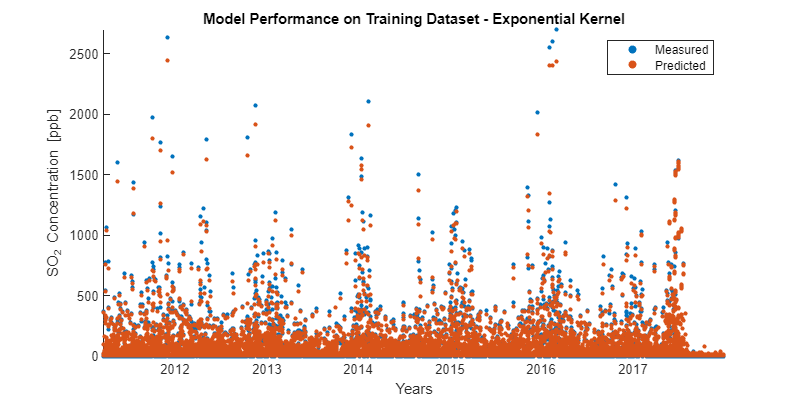

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_train, y_train, 10, 'filled')
hold on
scatter(t_train, y_train_pred(:, 1), 10, 'filled')
hold off
ylabel('SO_2 Concentration [ppb]')
xlabel('Years')
ylim([0, inf])
legend('Measured', 'Predicted')
title('Model Performance on Training Dataset - Exponential Kernel')

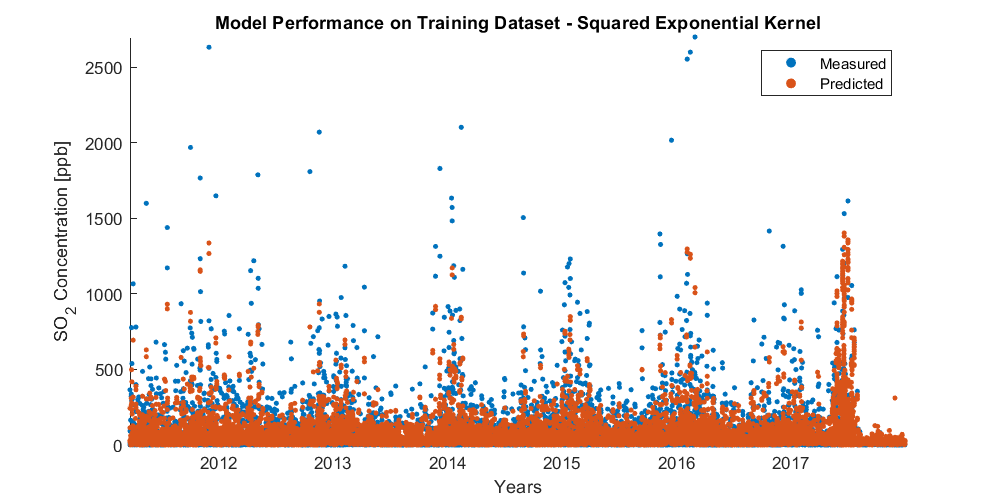

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_train, y_train, 10, 'filled')
hold on
scatter(t_train, y_train_pred(:, 2), 10, 'filled')
hold off
ylabel('SO_2 Concentration [ppb]')
xlabel('Years')
ylim([0, inf])
legend('Measured', 'Predicted')
title('Model Performance on Training Dataset - Squared Exponential Kernel')

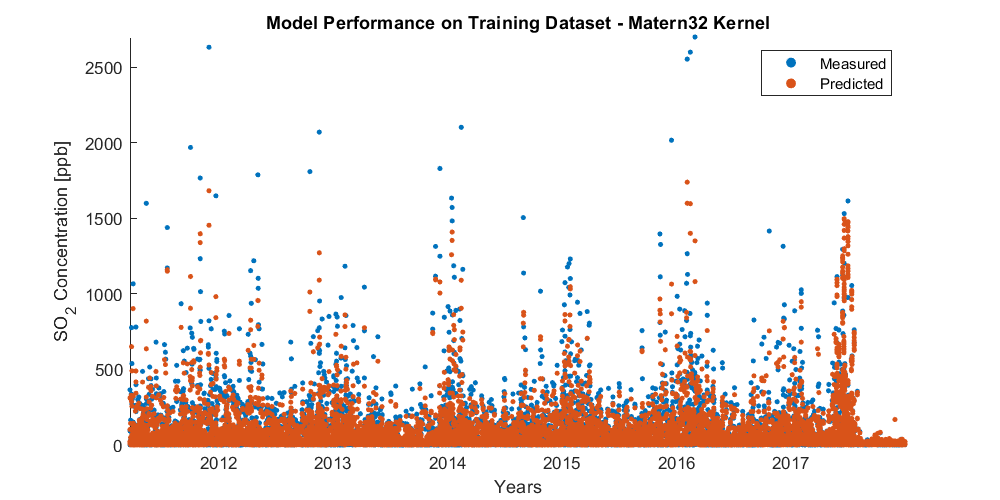

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_train, y_train, 10, 'filled')
hold on
scatter(t_train, y_train_pred(:, 3), 10, 'filled')
hold off
ylabel('SO_2 Concentration [ppb]')
xlabel('Years')
ylim([0, inf])
legend('Measured', 'Predicted')
title('Model Performance on Training Dataset - Matern32 Kernel')

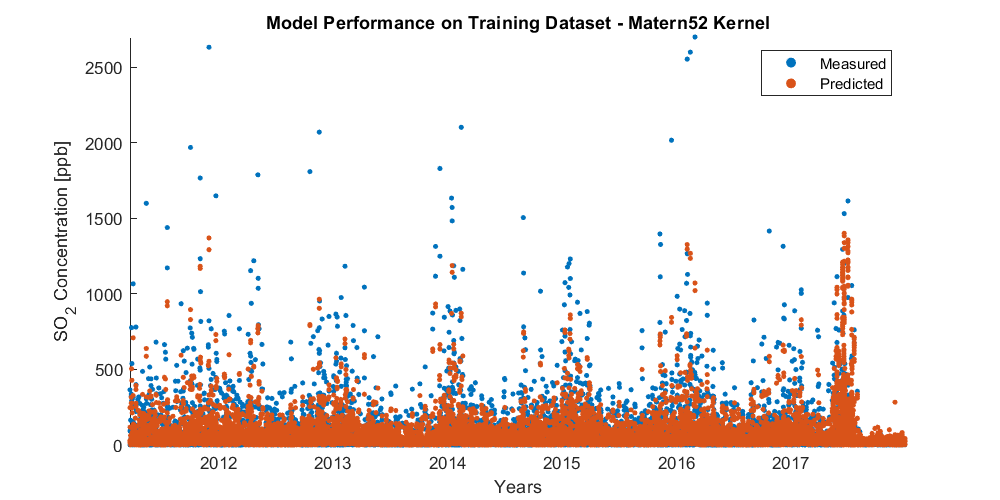

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_train, y_train, 10, 'filled')
hold on
scatter(t_train, y_train_pred(:, 4), 10, 'filled')
hold off
ylabel('SO_2 Concentration [ppb]')
xlabel('Years')
ylim([0, inf])
legend('Measured', 'Predicted')
title('Model Performance on Training Dataset - Matern52 Kernel')

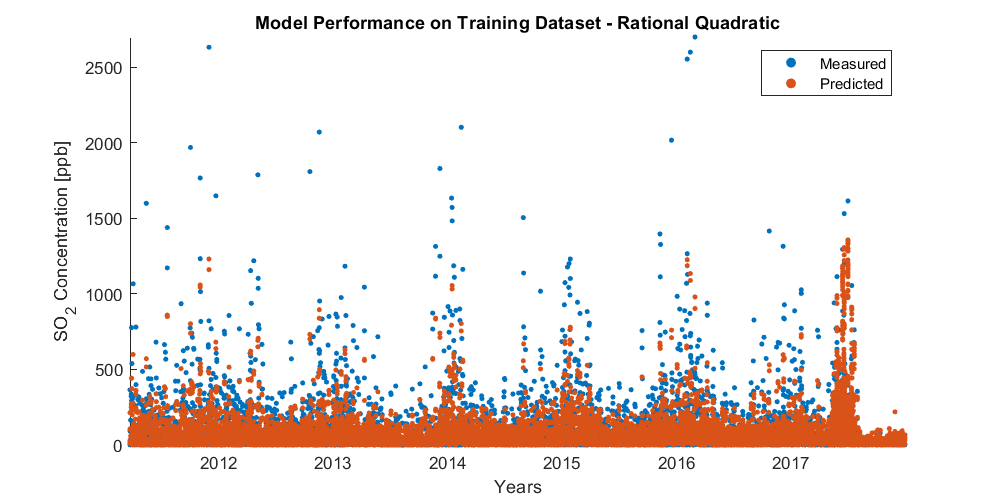

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_train, y_train, 10, 'filled')
hold on
scatter(t_train, y_train_pred(:, 5), 10, 'filled')
hold off
ylabel('SO_2 Concentration [ppb]')
xlabel('Years')
ylim([0, inf])
legend('Measured', 'Predicted')
title('Model Performance on Training Dataset - Rational Quadratic')

### Plots for Validation - Time Histories

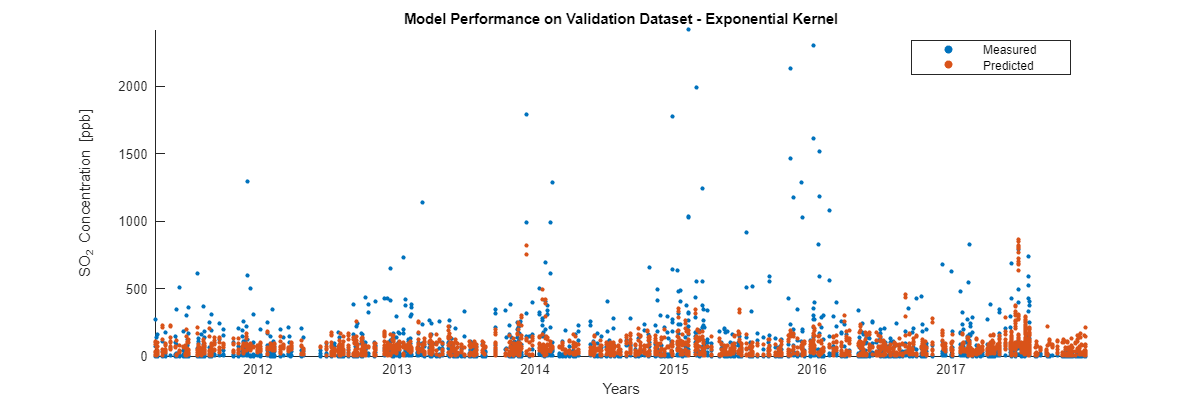

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_valid, y_valid, 10, 'filled')
hold on
scatter(t_valid, y_valid_pred(:, 1), 10, 'filled')
hold off
ylabel('SO_2 Concentration [ppb]')
xlabel('Years')
ylim([0, inf])
legend('Measured', 'Predicted')
title('Model Performance on Validation Dataset - Exponential Kernel')

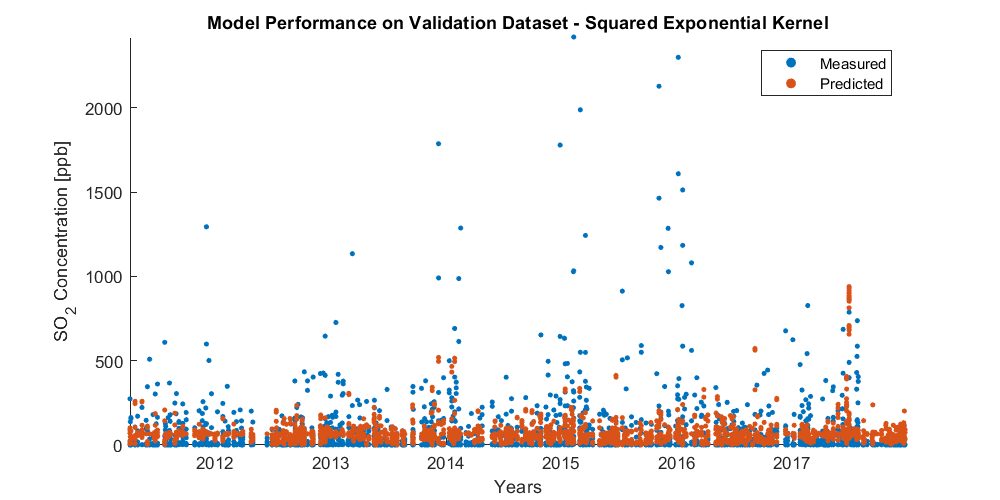

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_valid, y_valid, 10, 'filled')
hold on
scatter(t_valid, y_valid_pred(:, 2), 10, 'filled')
hold off
ylabel('SO_2 Concentration [ppb]')
xlabel('Years')
ylim([0, inf])
legend('Measured', 'Predicted')
title('Model Performance on Validation Dataset - Squared Exponential Kernel')

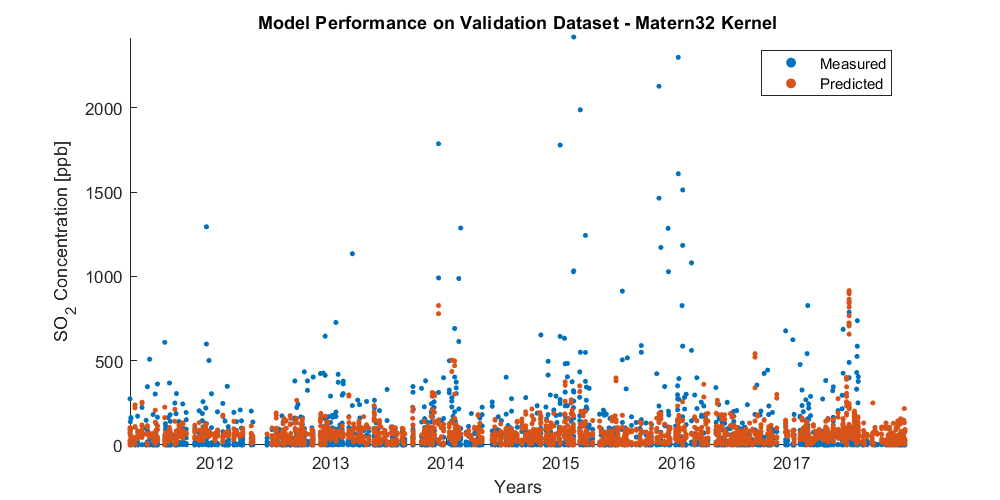

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_valid, y_valid, 10, 'filled')
hold on
scatter(t_valid, y_valid_pred(:, 3), 10, 'filled')
hold off
ylabel('SO_2 Concentration [ppb]')
xlabel('Years')
ylim([0, inf])
legend('Measured', 'Predicted')
title('Model Performance on Validation Dataset - Matern32 Kernel')

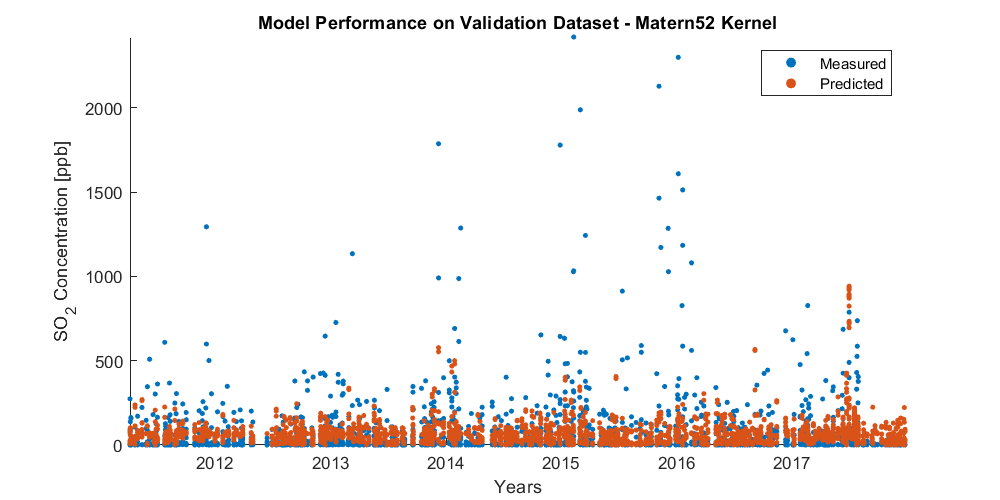

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_valid, y_valid, 10, 'filled')
hold on
scatter(t_valid, y_valid_pred(:, 4), 10, 'filled')
hold off
ylabel('SO_2 Concentration [ppb]')
xlabel('Years')
ylim([0, inf])
legend('Measured', 'Predicted')
title('Model Performance on Validation Dataset - Matern52 Kernel')

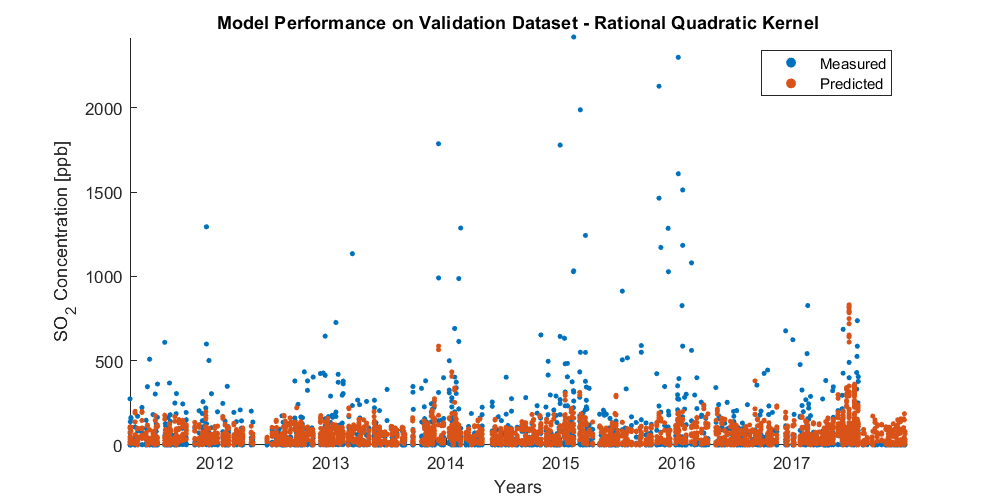

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_valid, y_valid, 10, 'filled')
hold on
scatter(t_valid, y_valid_pred(:, 5), 10, 'filled')
hold off
ylabel('SO_2 Concentration [ppb]')
xlabel('Years')
ylim([0, inf])
legend('Measured', 'Predicted')
title('Model Performance on Validation Dataset - Rational Quadratic Kernel')

### Calculate Performance Metrics for Validation Dataset

% Root Mean Squared Errors
MSE_1 = immse(y_valid_pred(:, 1), y_valid);
MSE_2 = immse(y_valid_pred(:, 2), y_valid);
MSE_3 = immse(y_valid_pred(:, 3), y_valid);
MSE_4 = immse(y_valid_pred(:, 4), y_valid);
MSE_5 = immse(y_valid_pred(:, 5), y_valid);
MSE_valid = [MSE_1, MSE_2, MSE_3, MSE_4, MSE_5];
RMSE_valid = sqrt(MSE_valid);

% Average Least Absolute Error
MAE_1 = mean(abs(y_valid_pred(:, 1) - y_valid));
MAE_2 = mean(abs(y_valid_pred(:, 2) - y_valid));
MAE_3 = mean(abs(y_valid_pred(:, 3) - y_valid));
MAE_4 = mean(abs(y_valid_pred(:, 4) - y_valid));
MAE_5 = mean(abs(y_valid_pred(:, 5) - y_valid));
MAE_valid = [MAE_1, MAE_2, MAE_3, MAE_4, MAE_5];

Metrics = cat(1, RMSE_valid, MAE_valid);
Metrics_Table = array2table(Metrics, 'RowNames', {'RMSE [ppb]', 'MAE [ppb]'}, 'VariableNames', {'Exponential', 'Squared Exponential', 'Matern32', 'Matern52','Rational Quadratic'});

disp(Metrics_Table)

                  Exponential    Squared Exponential    Matern32    Matern52    Rational Quadratic
                  ___________    ___________________    ________    ________    __________________

    RMSE [ppb]      151.92              156.6            153.55      154.81           151.69      
    MAE [ppb]       68.708             73.711            70.042      70.975           67.594      



### Predict for Test - Select Model with Best Metrics - Rational Quadratic 

% Validation
y_test_pred = predict(gprMdl_5, x_test);

% Unnormalize = 2,700
y_test_pred = y_test_pred * 2700;
y_test = y_test * 2700;
% Label Data
for i = 1:numel(y_test)
    if y_test_pred(i) > 5000
        y_test_label(i) = 5;
    elseif y_test_pred() > 3000
        y_test_label(i) = 4;
    elseif y_test_pred(i) > 1000
        y_test_label(i) = 3;
    elseif y_test_pred(i) > 200
        y_test_label(i) = 2;
    elseif y_test_pred(i) > 100
        y_test_label(i) = 1;
    else
        y_test_label(i) = 0;
    end
end

### Calculate Performance Metrics for Test Dataset - Rational Quadratic 

% Root Mean Squared Errors
MSE_test = immse(y_test_pred, y_test);
RMSE_test = sqrt(MSE_test);

% Average Least Absolute Error
MAE_test = mean(abs(y_test_pred - y_test));

Metrics = cat(1, RMSE_test, MAE_test);
Metrics_Table = array2table(Metrics, 'RowNames', {'RMSE [ppb]', 'LAE [ppb]'}, 'VariableNames', {'Rational Quadratic'});
disp(Metrics_Table)

                  Rational Quadratic
                  __________________

    RMSE [ppb]          160.87      
    LAE [ppb]           63.445      



### Plots on Test Dataset - Time History

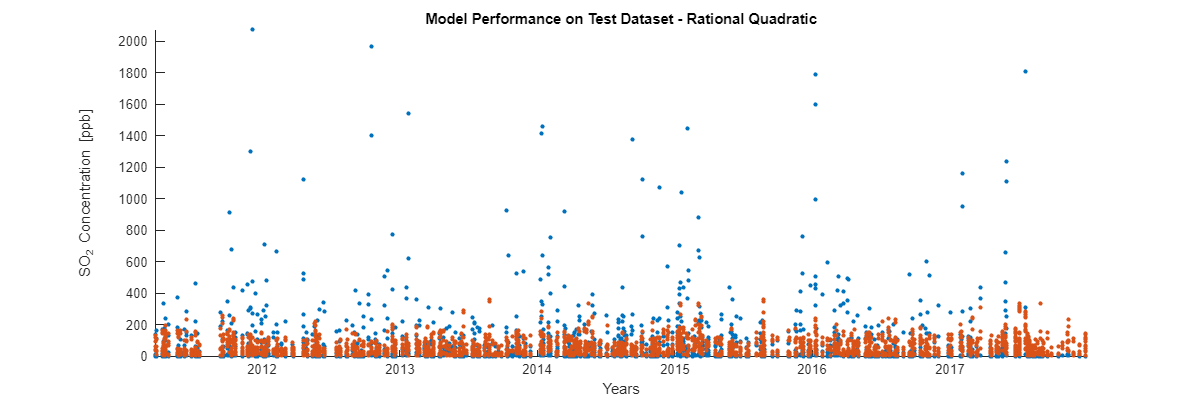

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_test, y_test, 10, 'filled')
hold on
scatter(t_test, y_test_pred, 10, 'filled')
hold off
ylabel('SO_2 Concentration [ppb]')
xlabel('Years')
ylim([0, inf])
title('Model Performance on Test Dataset - Rational Quadratic')

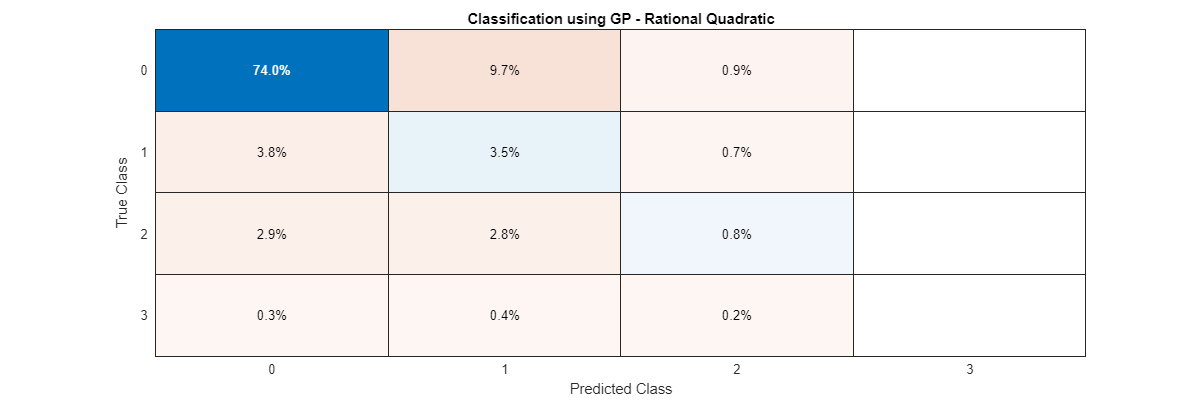

% Plot Confussion Matrix
fig = figure('Position', [0,0,1200,400]);
confusionchart(Testing_Data_Table.Risk_Label, y_test_label, 'Normalization', 'total-normalized');
title('Classification using GP - Rational Quadratic')